# BME 2740 Interactive Lecture 14

# By: Dr. Asad Mirza

# Adapted From: Dr. Ilmar Tamames

## Numerical Integration Extended

#### Large Simulation Optimization: Scenario 1

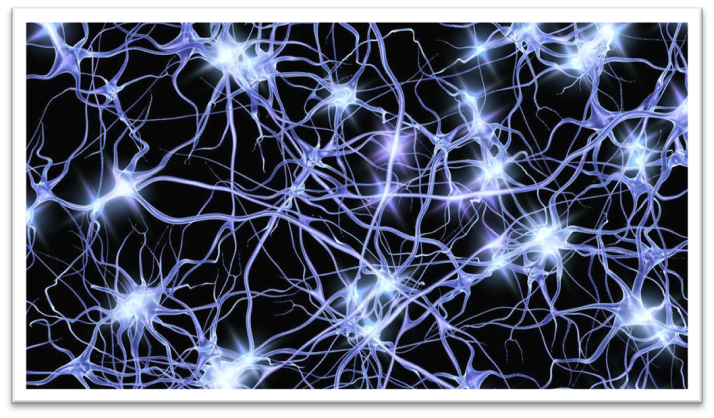

Neurodegenerative diseases, including multiple sclerosis (MS), Parkinson’s disease, Alzheimer’s disease, and ALS, can disrupt normal neural function. As a scientific advisor to the fictional Snacks and Supplements Bureau, you are tasked with evaluating claims that a new supplement can alter neuronal activity.

Using the FitzHugh–Nagumo neuron model, investigate how changes in parameters (a), (b), and (c) affect neuronal excitability and recovery dynamics. The supplement developers claim that decreasing (a), increasing (b), and decreasing (c) will increase neuronal activity. Simulate the model over 200 ms and examine how these parameter changes affect the voltage response and number of action-potential-like peaks.


$$\begin{array}{c}
\frac{dv}{dt}=v-\frac{v^3 }{3}-w+I\\
\frac{dw}{dt}=c\left(v+a-\textrm{bw}\right)
\end{array}$$


- a: Affects neuronal excitability and threshold behavior.

- b: Affects recovery dynamics

- c: Controls the recovery rate smaller values mean slower recovery.

Where v is the voltage and w is the linear recovery of the neuron.

Assuming we have initial values for a,b, and c. How many peaks can we find during 200 ms for a neuron activity?    

clear,clc,close all

% % Step 1 Set up 
% Set up parameters for neuron model
a = 0.1;   % Parameter a, influences rheobase level
b = 0.7;    % Parameter b, influences membrane conductance
c = 0.05;   % Parameter c, influences recovery rate

I = 0.5;     % External current input
h = 0.001;    % Time step for Euler's method, try out other values (1, 0.5, etc)

% Static variables
t = 0:h:200; % Time vector from 0 to 200 ms with step size h




% % Step 2 Timer 

% Initialize the neuron state matrix
Neuron_M1 = zeros(length(t), 2);  % Preallocate neuron states (2 variables)
Neuron_M1(1, :) = [0, 0];         % Initial state of the neuron

% Define the differential equations using an anonymous function system
f = @(t,s) [s(1) - s(1)^3 / 3 - s(2) + I, ... % First equation dv/dt
          c * (s(1) + a - b * s(2))];       % Second equation dw/dt
tic % Start timer
% Apply forward Euler method - Matrix Style
for k = 1:length(t) - 1
    Neuron_M1(k + 1, :) = Neuron_M1(k, :) + h * f(t(k),Neuron_M1(k, :)); % Update neuron state
end
% End timer
toc_forward = toc

toc_forward = 0.0697

% % Alternate Method for Step 2 - Sequential Style
% Initialize the neuron state matrix
Neuron_M2_w_plot = zeros(length(t), 1);  % Preallocate neuron states (2 variables)
Neuron_M2_v_plot = zeros(length(t), 1);  

current_v = Neuron_M2_v_plot(1);
current_w = Neuron_M2_w_plot(1);

% Define the differential equations using multiple anonymous functions
f1 = @(v,w) v - v.^3 / 3 - w + I;        % First equation dv/dt
f2 = @(v,w) c * (v + a - b * w);        % Second equation dw/dt

tic
for k = 1:length(t)-1
    % Update v using current v and w
    new_v = current_v + h * f1(current_v, current_w);
    % Update w using the current w
    new_w = current_w + h * f2(current_v, current_w);
    % Update current v and w with new values
    current_v = new_v;
    current_w = new_w;
    % Store for plotting
    Neuron_M2_w_plot(k+1)=new_w;
    Neuron_M2_v_plot(k+1)=new_v;
end
toc

Elapsed time is 0.042175 seconds.


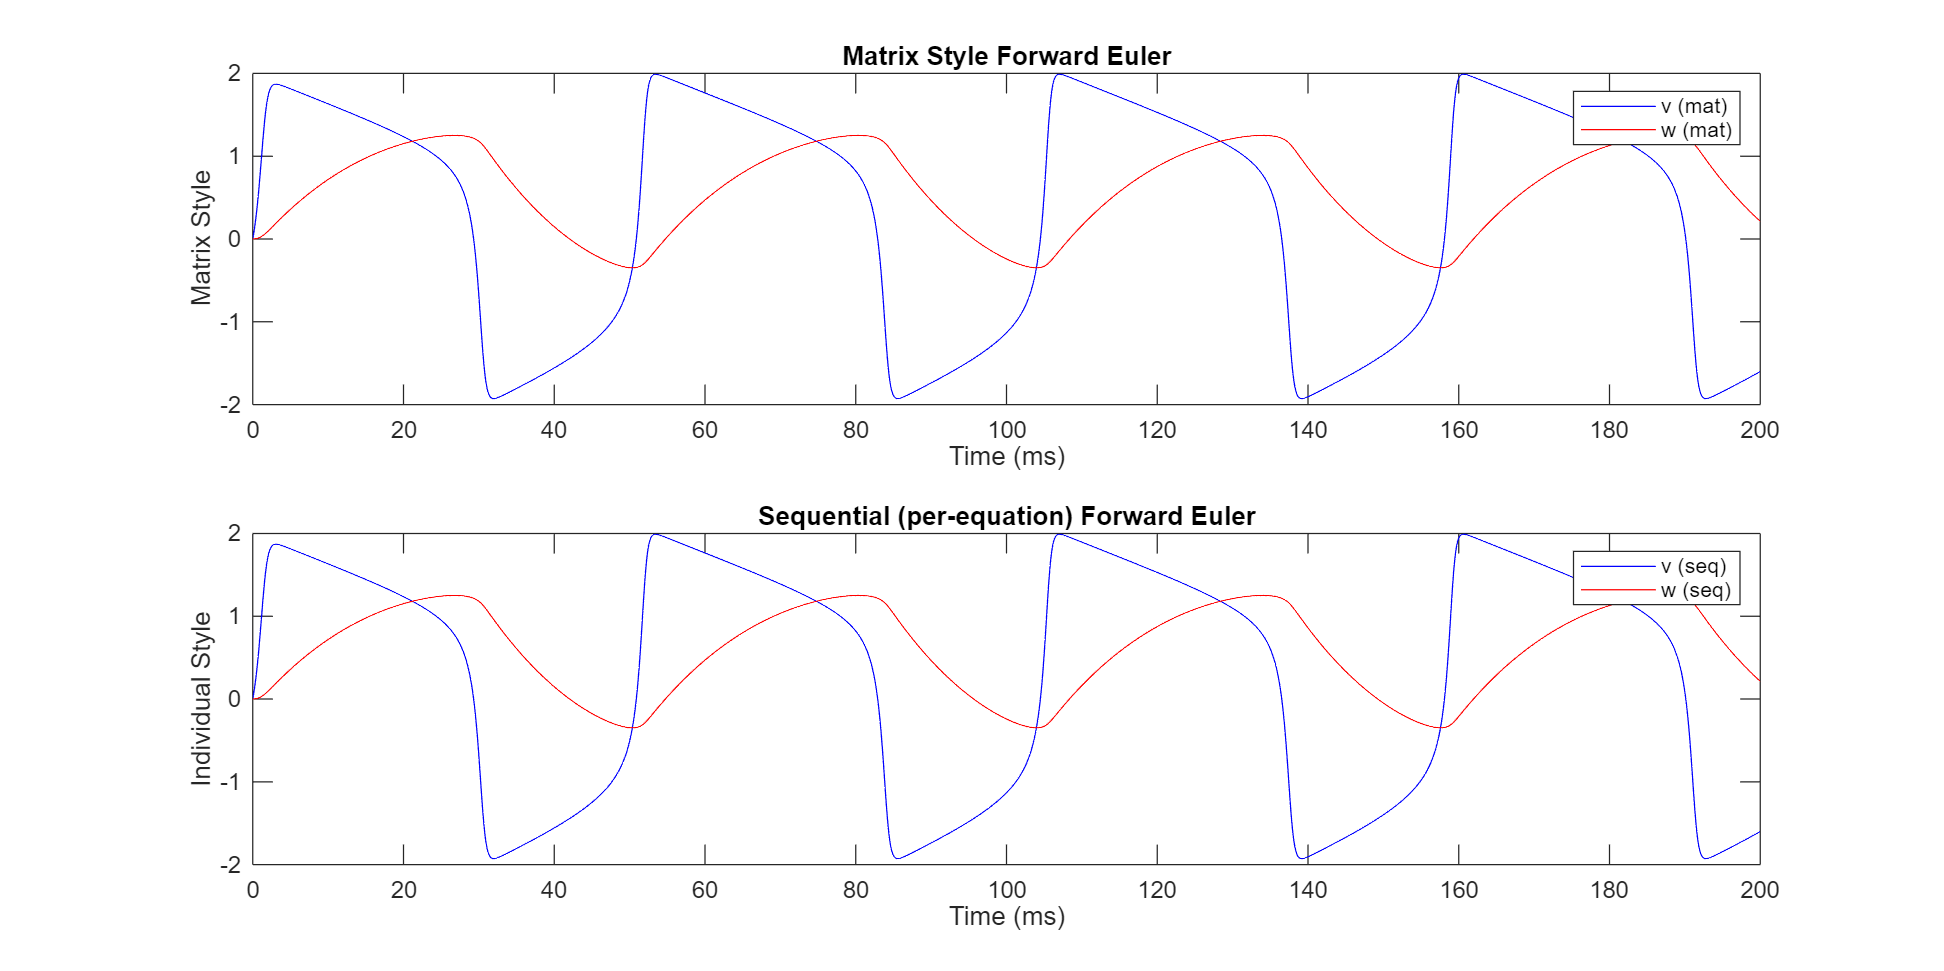

% % Step 3 : Visual


figure('Units','normalized','Position',[0.1 0.1 0.75 0.6]);

subplot(2,1,1)
plot(t, Neuron_M1(:,1), 'b', t, Neuron_M1(:,2), 'r');
xlabel('Time (ms)')
ylabel('Matrix Style')
legend('v (mat)','w (mat)','Location','northeast')
title('Matrix Style Forward Euler')

subplot(2,1,2)
plot(t, Neuron_M2_v_plot, 'b', t, Neuron_M2_w_plot, 'r');
xlabel('Time (ms)')
ylabel('Individual Style')
legend('v (seq)','w (seq)','Location','northeast')
title('Sequential (per-equation) Forward Euler')

TIP: [Tic Toc](https://www.mathworks.com/help/matlab/ref/tic.html)

% Display time for simulation
fprintf("1 run took %3.7f seconds.",toc_forward)

1 run took 0.0697354 seconds.

If we wish to test all combinations of 100 values of the three parameters:

fprintf("100x100x100 runs may take ~%3.2f minutes.",toc_forward*100^3/60)

100x100x100 runs may take ~1162.26 minutes.

Changing h will only increase the time or decrease the accuracy.

What to do?

## Side Note - Finding Peaks

[pks, locs] = findpeaks(Neuron_M1(:,1), t);

fprintf('Number of detected peaks: %d\n', length(pks));

Number of detected peaks: 4


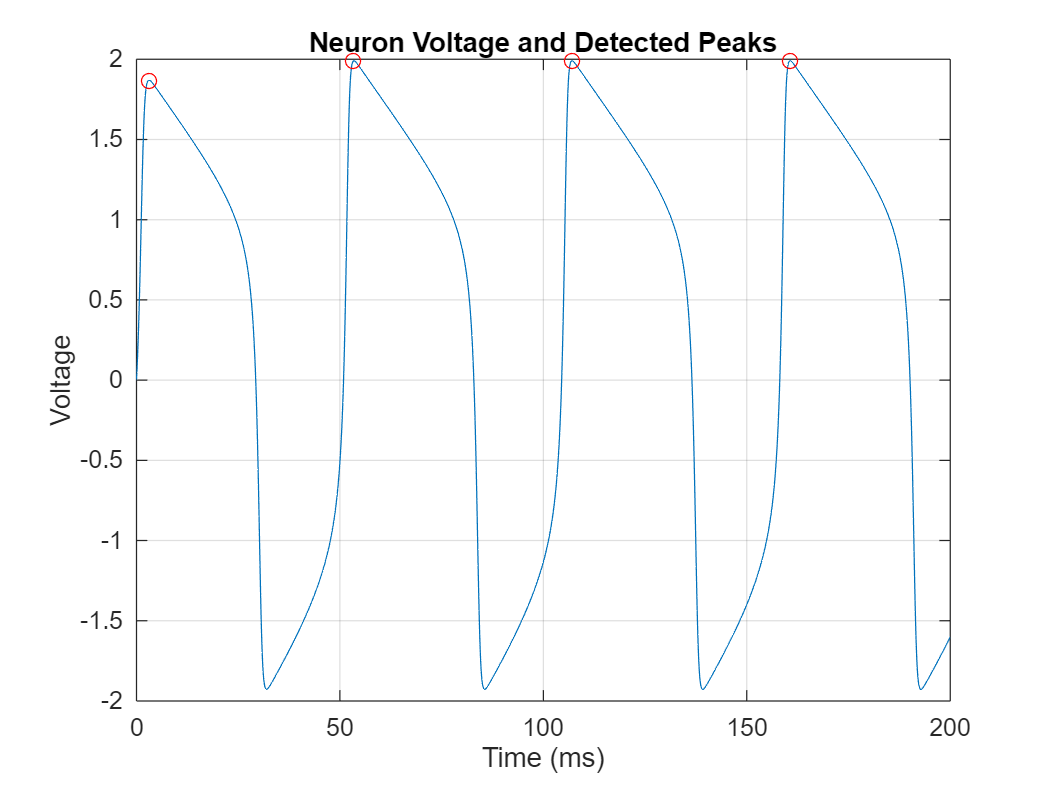


figure
plot(t, Neuron_M1(:,1))
hold on
plot(locs, pks, 'ro')
xlabel('Time (ms)')
ylabel('Voltage')
title('Neuron Voltage and Detected Peaks')
grid on

## The Adaptive Step Size

Reduce the step-size, "h",  only when we “need to”. Meaning only reduce the step-size when error estimates become large or the rate of change becomes large.

This is the main idea:

- Slow changes → increase h.

- Rapid changes → decrease h.

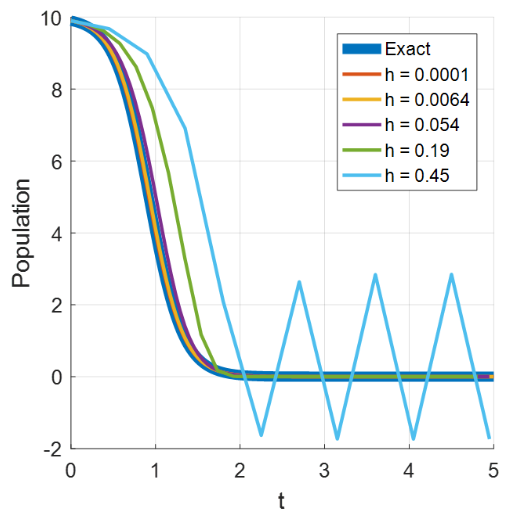

## Adaptive step size solver

Adaptive solvers estimate the local numerical error and adjust the time step to meet specified error tolerances.

- When the solution changes rapidly, the solver generally takes smaller steps.

- When the solution changes slowly, the solver can take larger steps.

- If a trial step fails the error test, the solver reduces the step size and retries.

This approach can reduce computational cost while maintaining the requested accuracy.

The solver does NOT use a small step size all the time.

Instead, it monitors the accuracy of its calculations!!!

Example of adaptive step-size adjustment

//// EXAMPLE

Initial step : h = 0.1 

>> Error acceptable >> The solver accepts the step and continues.

Next trial: h = 0.1

>> Error too large >> The solver rejects the step and tries again with a smaller h.

Retry : h = 0.05

>> Error acceptable >> The solver accepts this step.

Later, when solution is smooth: h = 0.2

Larger step accepted. The solver can save computation time by taking bigger steps.

\\\\\\

#### Example: ode45

`[`[`t`](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-t)`,`[`y`](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-y)`] = ode45(`[`odefun`](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-odefun)`,`[`tspan`](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-tspan)`,`[`y0`](https://www.mathworks.com/help/matlab/ref/ode45.html#bu00_4l_sep_shared-y0)`)`, where `tspan = [t0 tf]`, integrates the system of differential equations *y*′=*f*(*t*,*y*) from `t0` to `tf` with initial conditions `y0`. Each row in the solution array `y` corresponds to a value returned in column vector `t`.

***[t, y] = ode45 (function, time interval, initial condition) ***

////// SUMMARY:

**Requiered Format:** MATLAB's ODE solvers, such as `ode45`, are designed to solve systems written in this format: **y′=f(t,y)**

For example, if your state vector is:

    | y 1|

y=|      |

    | y 2|

MATLAB wants:

     | y'1|            | f1(t,y1,y2) |

y'=|      |     =     | f2(t,y1,y2) |

     | y'2|

**Determining # of state variables :** The number of state variables needed is determined by the highest derivative order in each differential equation:

ex.)  y′′=−4y′−3y 

 Step 1: Find y1' and y2'

so  y1 = y  and  y2 = y'

This means y1' = y'

 Since y2 = y' = y1' ,  therefore y2' = (y1')' = (y')'. Then y2' = y''

Step 2: Plug in

y2' = - 4y2 - 3y1

Step 3: As a vector

     | y'1|            | y2             |

y'=|      |     =     | - 4y2 - 3y1|

     | y'2|

Step 4: In code

% myODE is just an anonymous fucntion we chose for this exmaple, replace
% with your own anonymous fucntion

function dydt = myODE(t,y);

    dydt = zeros(2,1);

    dydt(1) = y(2);

    dydt(2) = -4*y(2) - 3*y(1);

end

% Now call ode45

tspan = [0 10];

y0 = [1; 0];

[t,y] = ode45(@myODE,tspan,y0);

\\\\\\ SUMMARY END 

TIP: [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html)

### Scenario 1 revisited

clear,clc,close all
% Set up parameters for neuron model
a = 0.1;   % Parameter a, influences rheobase level
b = 0.7;    % Parameter b, influences membrane conductance
c = 0.05;   % Parameter c, influences recovery rate

% Static variable for external input current
I = 0.5;

MATLAB wants what is called the **derivative of the state system,** $s^{\prime }$**,** as the input for $\textrm{odefun}$.

A state variable is just a holder for a bunch of variables $s=\left\lbrack v,w,\frac{\textrm{dv}}{\textrm{dt}},\frac{\textrm{dw}}{\textrm{dt}},\frac{d^2 v}{{\textrm{dt}}^2 },\frac{d^2 w}{{\textrm{dt}}^2 },\textrm{etc}\right\rbrack$

MATLAB's ODE solvers require a system of first-order differential equations.

Each independent state variable is included in the state vector. If a model contains higher-order differential equations, introduce additional state variables to rewrite the equations as a first-order system. General rule being as many state variables as the highest order deriative for each equation.

For   $\begin{array}{c}
\frac{dv}{dt}=v-\frac{v^3 }{3}-w+I\\
\frac{dw}{dt}=c\left(v+a-\textrm{bw}\right)
\end{array}$ 

the highest degree in either equation is 1, so we need 2 state variables, $\left\lbrack v\;\;w\right\rbrack$.


$$\;s=\left\lbrack \begin{array}{c}
v\\
w
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack$$


Remember that MATLAB doesn't want $s$ it instead wants $s^{\prime }$ so $s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v-\frac{v^3 }{3}-w+I\\
c\left(v+a-\textrm{bw}\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 -\frac{{s_1 }^3 }{3}-s_2 +I\\
c\left(s_1 +a-{\textrm{bs}}_2 \right)
\end{array}\right\rbrack$

This is the vector that MATLAB wants for $\textrm{odefun}:@\left(t,s\right)\;\left\lbrack \begin{array}{c}
s_1 -\frac{{s_1 }^3 }{3}-s_2 +I\\
c\left(s_1 +a-{\textrm{bs}}_2 \right)
\end{array}\right\rbrack$

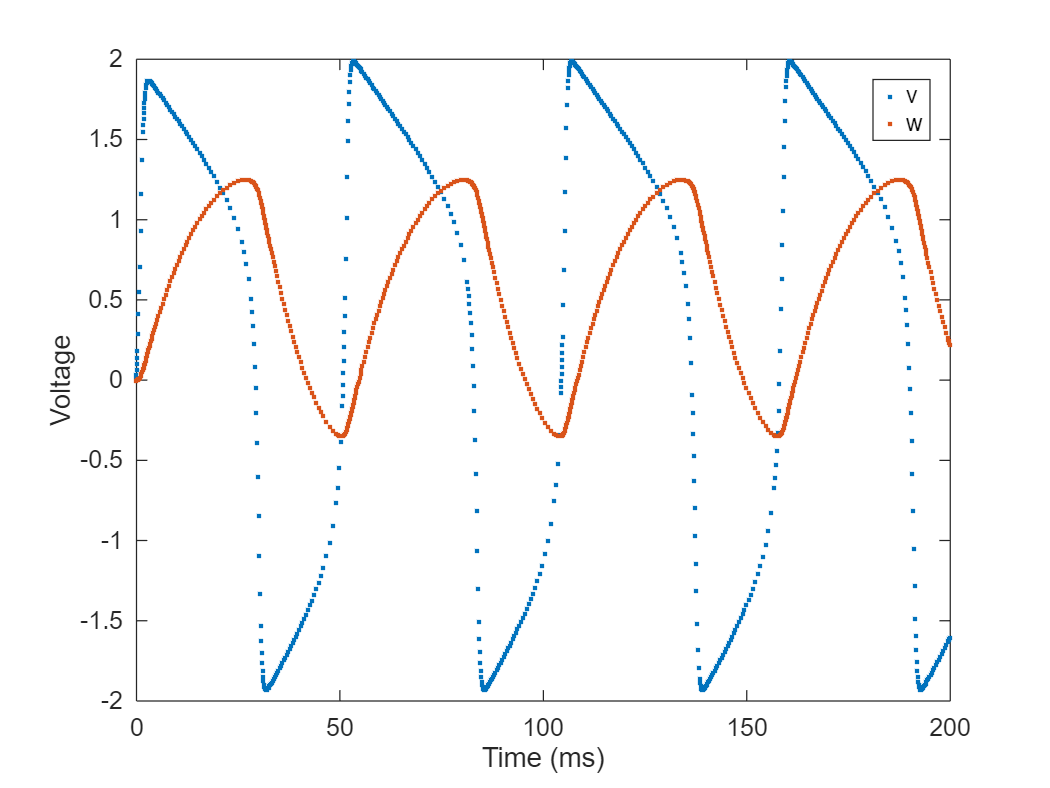

% Define the system of differential equations using an anonymous function
f = @(t, s) [s(1) - s(1)^3 / 3 - s(2) + I; ...  % First equation
             c * (s(1) + a - b * s(2))];       % Second equation

% Start timer
tic 
% "tic" starts a timer, it allows us to measure how long MATLAB takes to solve the differential equations.


% Use ODE45 solver for numerical integration from t = 0 to t = 200
[t, Neuron] = ode45(f, [0 200], [0 0]);
                                % ^ Initial conditions for both state variables


% End timer
toc_ODE45 = toc; 


% Plot the solution
figure
plot(t, Neuron, '.', 'MarkerSize', 5)
xlabel('Time (ms)')
ylabel('Voltage')
legend('v', 'w', 'Location', 'northeast')

% Display elapsed time for simulation
fprintf("1 run took %3.7f seconds.\n", toc_ODE45)

1 run took 0.0173052 seconds.


fprintf("100x100x100 runs may take ~%3.2f minutes.",toc_ODE45*100^3/60)

100x100x100 runs may take ~288.42 minutes.

#### ODE Function return

There is an inportant diffrence in how MATLAB handles ODE solutions

Previously, 

`[t, Neuron]`` = ode45(f, [0 200], [0 0]);`

MATLAB gives us two outputs:

- `t`: The time points.

- `Neuron`: The corresponding solution values

Now we're using:

`fList`` = ode45(f, tSpan, [0 0]);`

- The main difference is that instead of asking MATLAB to return the time values and solution values separately, we're asking it to return a solution structure. 

- Using : deval(fList, t) % returns the values of our state variables t those times, using interpolation 

Step 1: Set up >> fList = ode45(f,tSpan,[0 0]);

Step 2: Select time points >> t = linspace(0,200,1000);

Step 3: Eval using deval >>  deval(fList,t)

clear,clc,close all
% Parameters for neuron model
a = 0.1;   % Parameter a, influences rheobase level
b = 0.7;    % Parameter b, influences membrane conductance
c = 0.05;   % Parameter c, influences recovery rate

% Static input current
I = 0.5;

% Time span for the simulation
tSpan = [0 200];

% Define the system of differential equations
f = @(t, s) [s(1) - s(1)^3 / 3 - s(2) + I; ...  % First equation for voltage
             c * (s(1) + a - b * s(2))];        % Second equation for recovery variable
tic


% % % Now apply what we just learned: 

% Solve the system using ode45 and save solution structure
fList = ode45(f, tSpan, [0 0])

fList = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 4.0190e-04 0.0024 0.0125 0.0627 0.3139 0.9098 1.7244 1.9778 2.2313 2.8041 3.3327 4.0275 4.9201 6.1370 7.6521 9.2428 10.8579 12.6079 14.5533 16.7094 19.1705 22.2438 26.0229 28.2034 29.1900 29.9452 30.7003 31.1211 31.5419 … ] (1×160 double)
          y: [2×160 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


toc

Elapsed time is 0.044819 seconds.


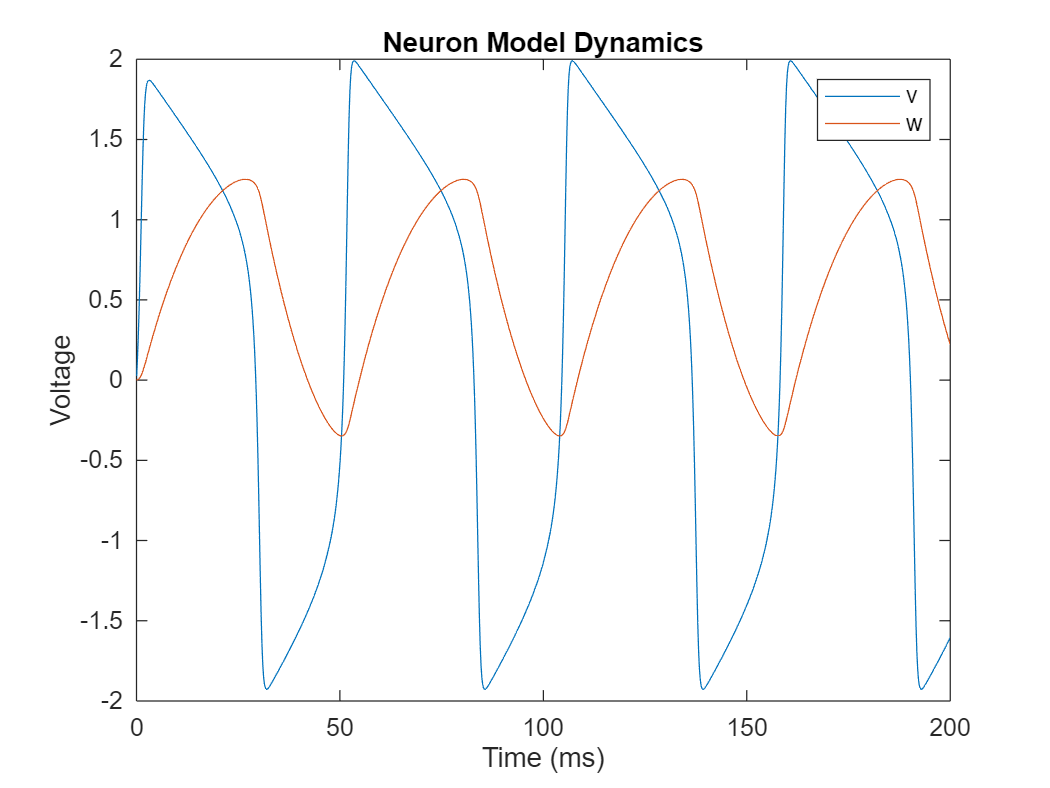

% Define a vector for evaluation points
t = linspace(0, 200, 1000);  % aka time point range

% Plot the solution
% You can use deval to evaluate a solved ODE at a specific time point
figure
plot(t, deval(fList, t))  % deval evaluates the solution at points in t
xlabel('Time (ms)')
ylabel('Voltage')
legend('v', 'w', 'Location', 'northeast')
title('Neuron Model Dynamics')

#### Implementation Example: Predator-Prey

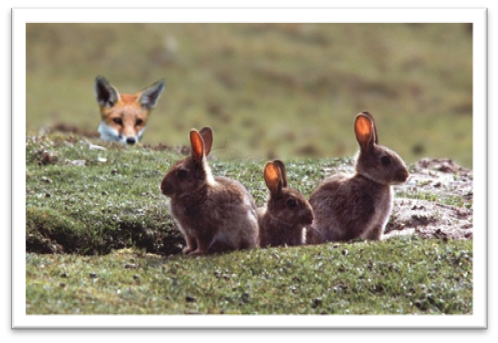

Solve:


$$\begin{array}{c}
\frac{dp_r }{dt}=1.2p_r -0.6p_r p_f \\
\frac{dp_f }{dt}=-0.8p_f +0.3p_r p_f 
\end{array}$$


with y1(0)=2 and y2(0)=1  for 20 seasons

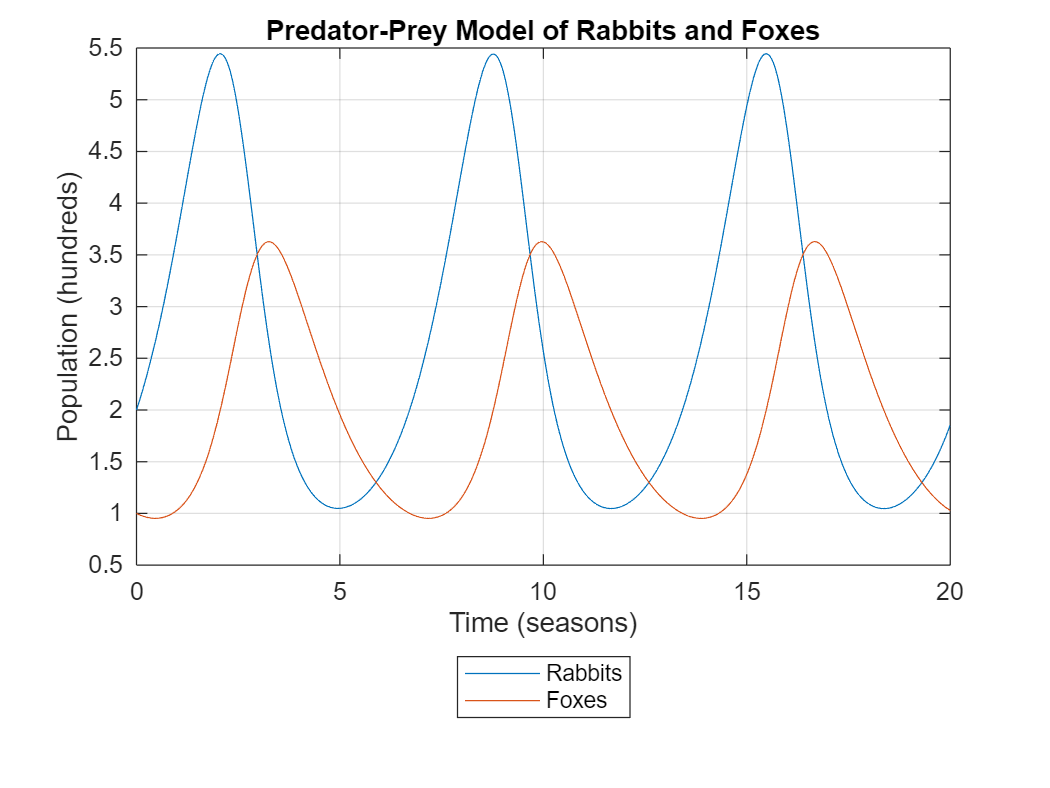

clear,clc,close all
% Set up the time span and initial populations
tspan = [0 20];  % Time range from 0 to 20 (seasons)
s0 = [2, 1];     % Initial populations: 2 for rabbits, 1 for foxes

% Define the predator-prey system of equations
% The first equation models the growth of rabbits with predation
% The second equation models the growth of foxes with a dependence on rabbit availability
predprey = @(t, s) [1.2 * s(1) - 0.6 * s(1) * s(2);...   % Rabbits' equation
                    -0.8 * s(2) + 0.3 * s(1) * s(2)];    % Foxes' equation

% Solve the system using ode45
% [t, y] = ode45(predprey, tspan, y0);      % y contains the solution
foxrab = ode45(predprey, tspan, s0);      % Store the solution as a function for deval

% Plot the solution
figure;
t = linspace(0, 20, 1000);                      % Create a time vector for smooth plotting
plot(t, deval(foxrab, t))                 % Use deval to evaluate the solution at each point in t
xlabel('Time (seasons)')
ylabel('Population (hundreds)')
legend('Rabbits', 'Foxes', 'Location', 'southoutside')
title('Predator-Prey Model of Rabbits and Foxes')
grid on;

#### Implementation Example: Lidocaine concentrations

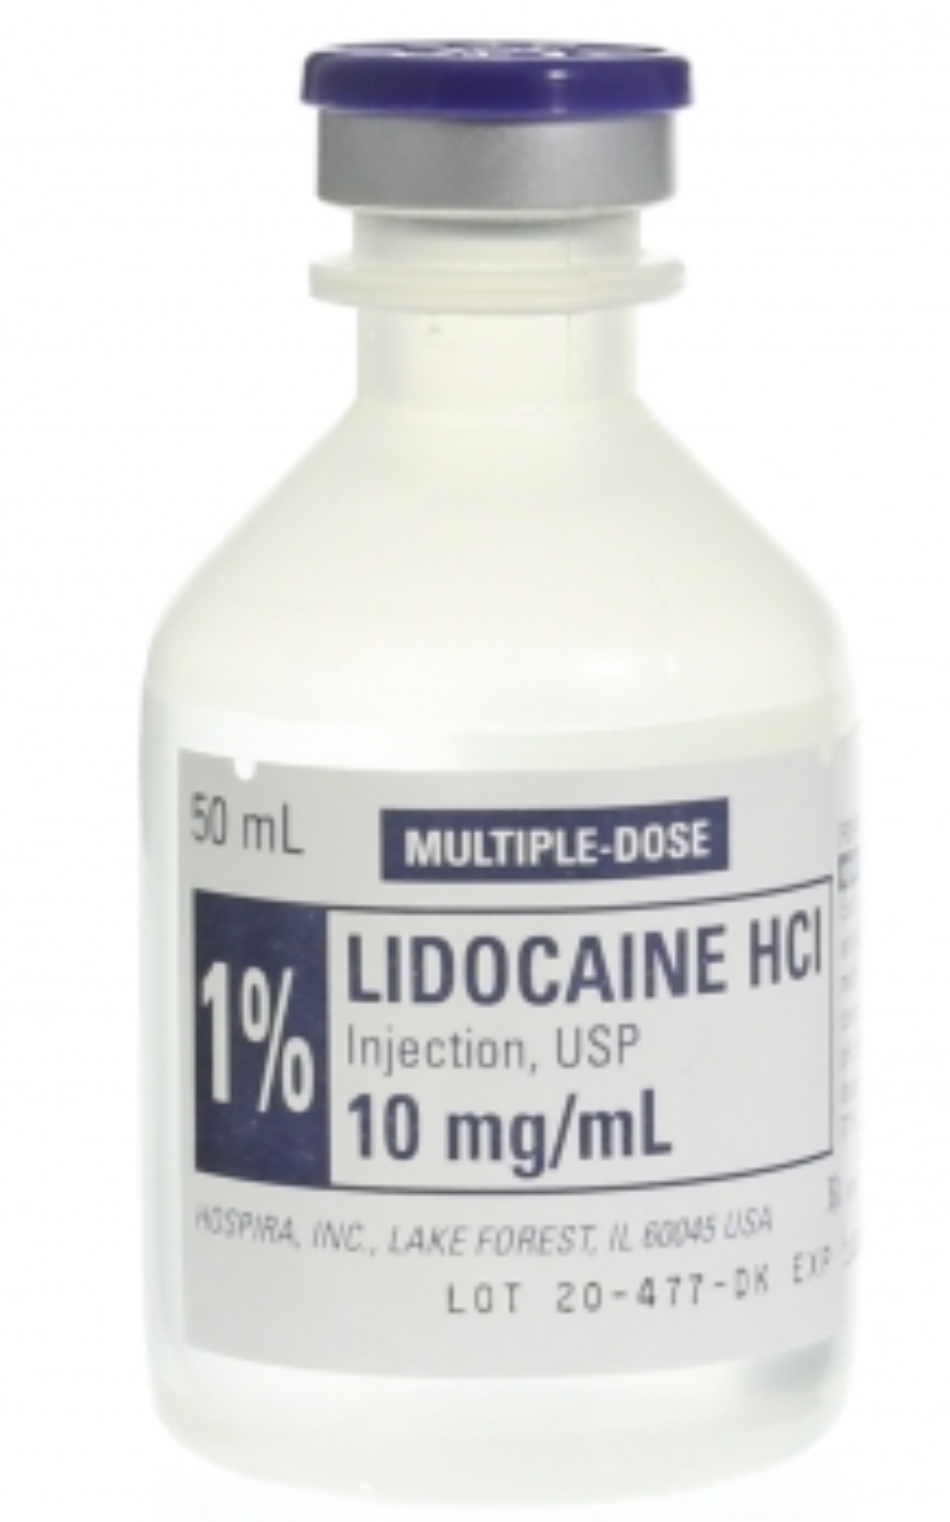

Solve:


$$\frac{\textrm{dx}}{\textrm{dt}}=-0\ldotp 090x\left(t\right)+0\ldotp 038y\left(t\right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=0\ldotp 066x\left(t\right)-0\ldotp 038y\left(t\right)$$


Where $x\left(0\right)=0$ and $y\left(0\right)=15$. Plot during 150 minutes.

% Set up the time range and initial concentrations
tspan = [0 150];  % Time range from 0 to 150
s0 = [0, 15];     % Initial concentrations: 0 for y1, 15 for y2

% Define the system of equations
% The first equation models the rate of change of y1
% The second equation models the rate of change of y2
f = @(t, s) [-0.090 * s(1) + 0.038 * s(2);  ...  % Rate equation for y1
              0.066 * s(1) - 0.038 * s(2)]; % Rate equation for y2
 
% Solve the system using ode45
[t, y] = ode45(f, tspan, s0)

t =          0
    0.0001
    0.0002
    0.0003
    0.0004
    0.0008
    0.0012
    0.0017
    0.0021
    0.0043


y =          0   15.0000
    0.0001   14.9999
    0.0001   14.9999
    0.0002   14.9998
    0.0002   14.9998
    0.0005   14.9995
    0.0007   14.9993
    0.0010   14.9990
    0.0012   14.9988
    0.0025   14.9975


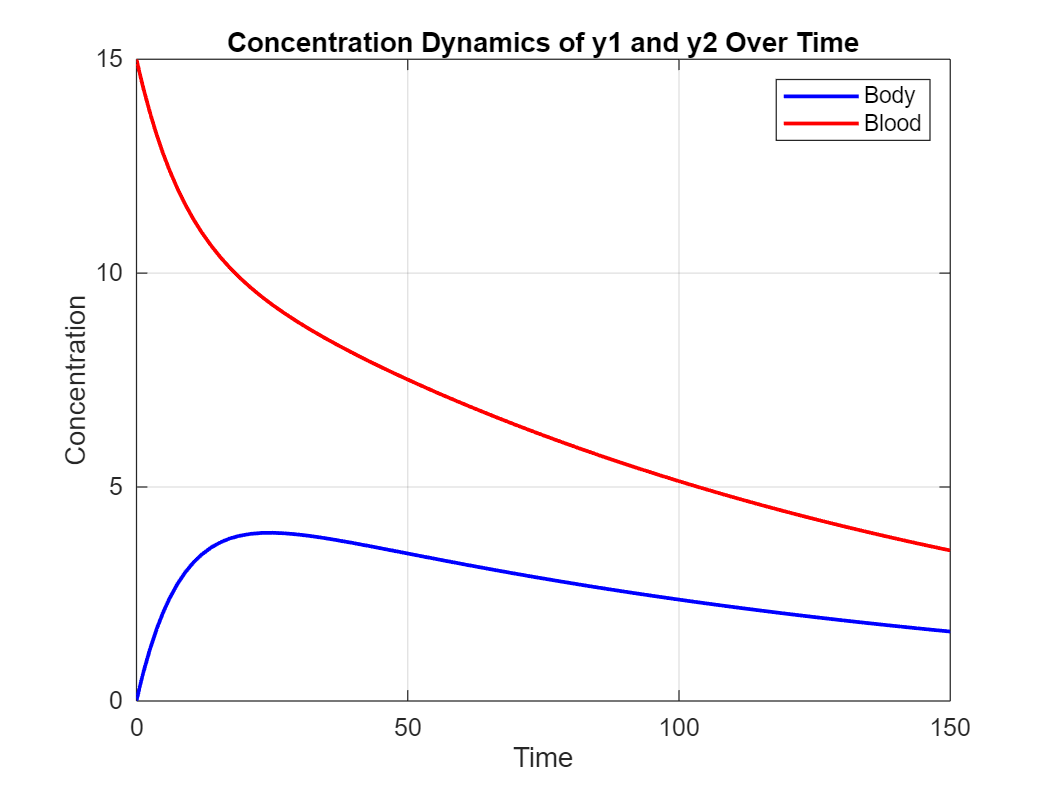


% Plot the solutions for y1 and y2 over time
figure;
plot(t, y(:, 1), 'b-', 'LineWidth', 1.5);  % Plot y1 in blue
hold on;
plot(t, y(:, 2), 'r-', 'LineWidth', 1.5);  % Plot y2 in red
hold off;

% Label the plot
xlabel('Time');
ylabel('Concentration');
title('Concentration Dynamics of y1 and y2 Over Time');
legend('Body', 'Blood', 'Location', 'northeast');
grid on;

#### Implementation Example: Brine Tank Cascade

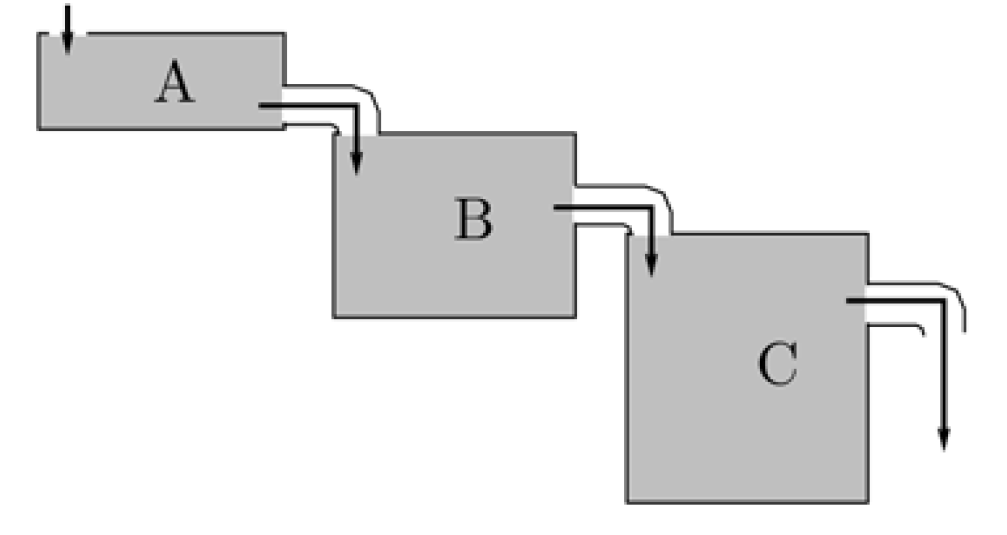

Solve:


$$\frac{dx_1 }{\textrm{dt}}=-\frac{1}{2}x_1$$



$$\frac{dx_2 }{\textrm{dt}}=\frac{1}{2}x_1 -\frac{1}{4}x_2$$



$$\frac{dx_3 }{\textrm{dt}}=\frac{1}{4}x_2 -\frac{1}{6}x_3$$


Where $x_1 \left(0\right)=x_2 \left(0\right)=x_3 \left(0\right)=50\;\textrm{mg}/L$. Plot over 100 minutes.

*Extra Challenge*: For the above problem, what is the difference in the number of numerical integration steps performed between `ode45` and Euler’s forward method using h = 0.05?

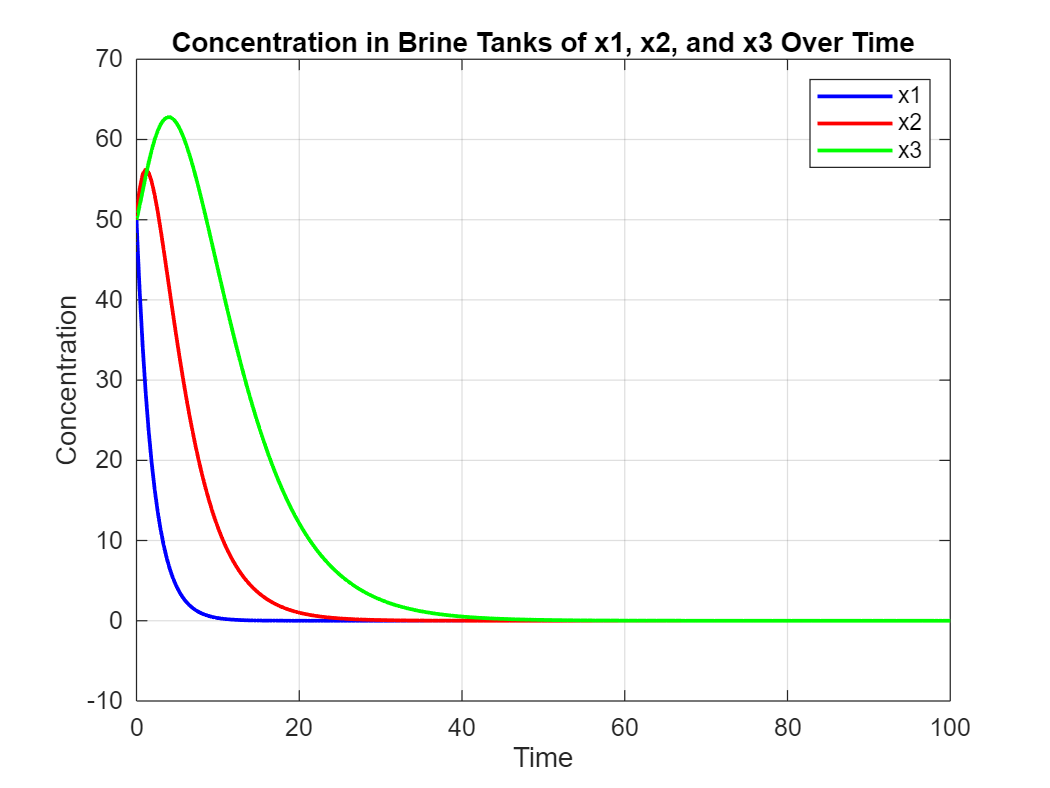

% Set up the time range and initial conditions for x1, x2, and x3
tspan = [0 100];  % Time range from 0 to 100
s0 = [50, 50, 50];  % Initial values: 50 for x1, x2, and x3

% Define the system of equations
% The first equation models the decay of x1
% The second equation models the interaction between x1 and x2
% The third equation models the interaction between x2 and x3
f = @(t, s) [-0.5 * s(1); ...                % Rate equation for x1
              0.5 * s(1) - 0.25 * s(2); ...  % Rate equation for x2
              0.25 * s(2) - (1/6) * s(3)];   % Rate equation for x3
 
% Solve the system using ode45
[t, y] = ode45(f, tspan, s0);

% Plot the solutions for x1, x2, and x3 over time
figure;
plot(t, y(:, 1), 'b-', 'LineWidth', 1.5);  % Plot x1 in blue
hold on;
plot(t, y(:, 2), 'r-', 'LineWidth', 1.5);  % Plot x2 in red
plot(t, y(:, 3), 'g-', 'LineWidth', 1.5);  % Plot x3 in green
hold off;

% Label the plot
xlabel('Time');
ylabel('Concentration');
title('Concentration in Brine Tanks of x1, x2, and x3 Over Time');
legend('x1', 'x2', 'x3', 'Location', 'northeast');
grid on;

% Bonus: Compare the length of output time vector with a specified time step vector
fprintf('Length of ode45 time vector: %d\n', length(t));

Length of ode45 time vector: 149


fprintf('Length of Euler''s Forward Method time vector: %d\n', length(0:0.05:100));

Length of Euler's Forward Method time vector: 2001


#### Selecting a solver

*Fixed-step solvers* solve the model at regular time intervals from the beginning to the end of the simulation. The size of the interval is known as the step size. You can specify the step size or let the solver choose the step size. Generally, a smaller the step size increases the accuracy of the results but also increases the time required to simulate the system.

*Variable-step solvers *vary the step size during the simulation. They reduce the step size to increase accuracy when a model's states are changing rapidly and increase the step size to avoid taking unnecessary steps when the model's states are changing slowly. Computing the step size adds to the computational overhead at each step but can reduce the total number of steps, and hence the simulation time required to maintain a specified level of accuracy for models with rapidly changing or piecewise continuous states.

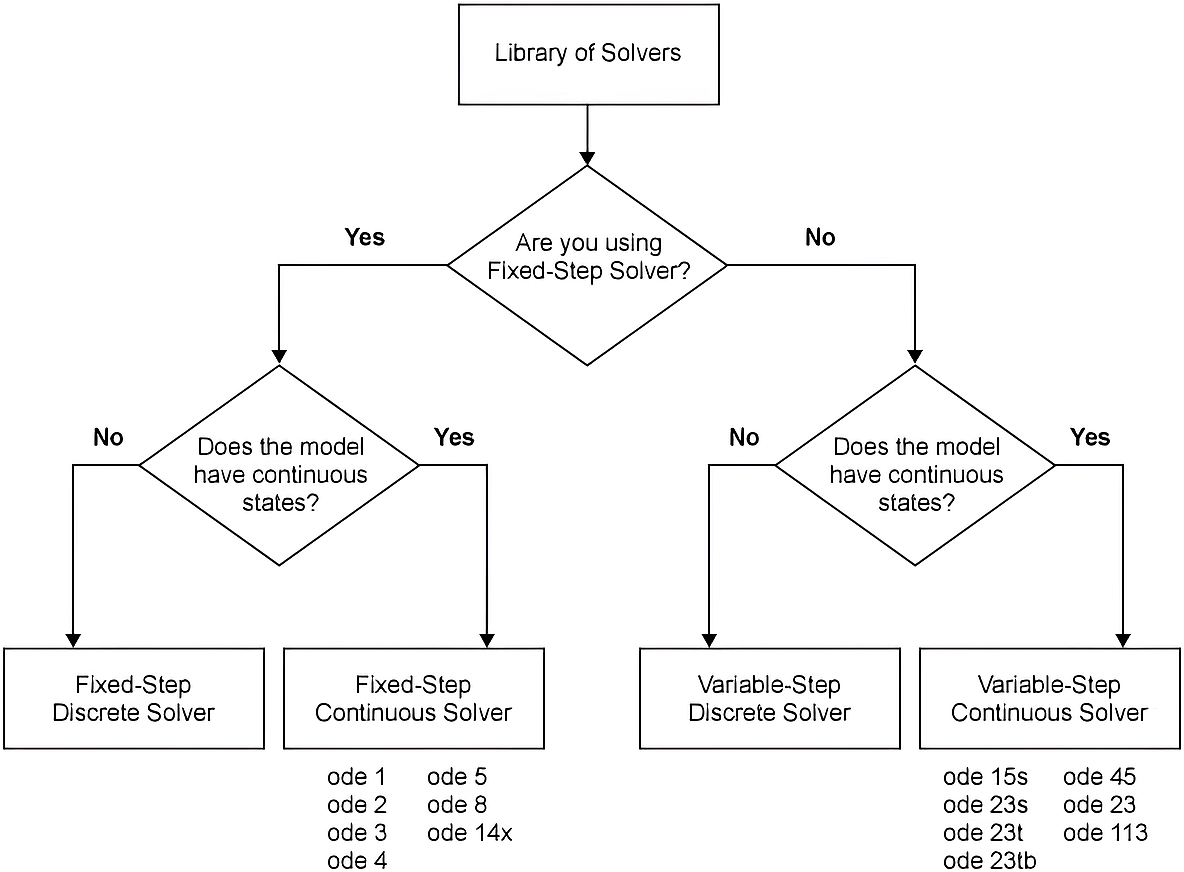

## Stiffness

Essentially, to ensure accurate approximation, a fixed-step solver has to have a small enough time step to capture the fastest timescale. Some ODE problems exhibit *stiffness*, or difficulty in evaluation. Stiffness is a term that defies a precise definition, but in general, stiffness occurs when there is a difference in scaling somewhere in the problem. For example, if an ODE has two solution components that vary on drastically different time scales, then the equation might be stiff. You can identify a problem as stiff if nonstiff solvers, such as `ode45,` are unable to solve the problem or are extremely slow. If you observe that a nonstiff solver is very slow, try using a stiff solver, such as `ode15s,` instead.

- Try ode45 first.

- Start with ode45 for a typical nonstiff ODE.

- If performance is poor, check the tolerances, model formulation, and solver output.

- If stiffness is suspected, compare with ode15s.

- Select the solver based on the problem's properties and the accuracy required.

- If ode15s is "slow" switch to ode23s.

- If ode23s is "slow" switch to ode23tb.

- If ode23tb is "slow" what kind of ODE are you even dealing with ?!? Contact me.

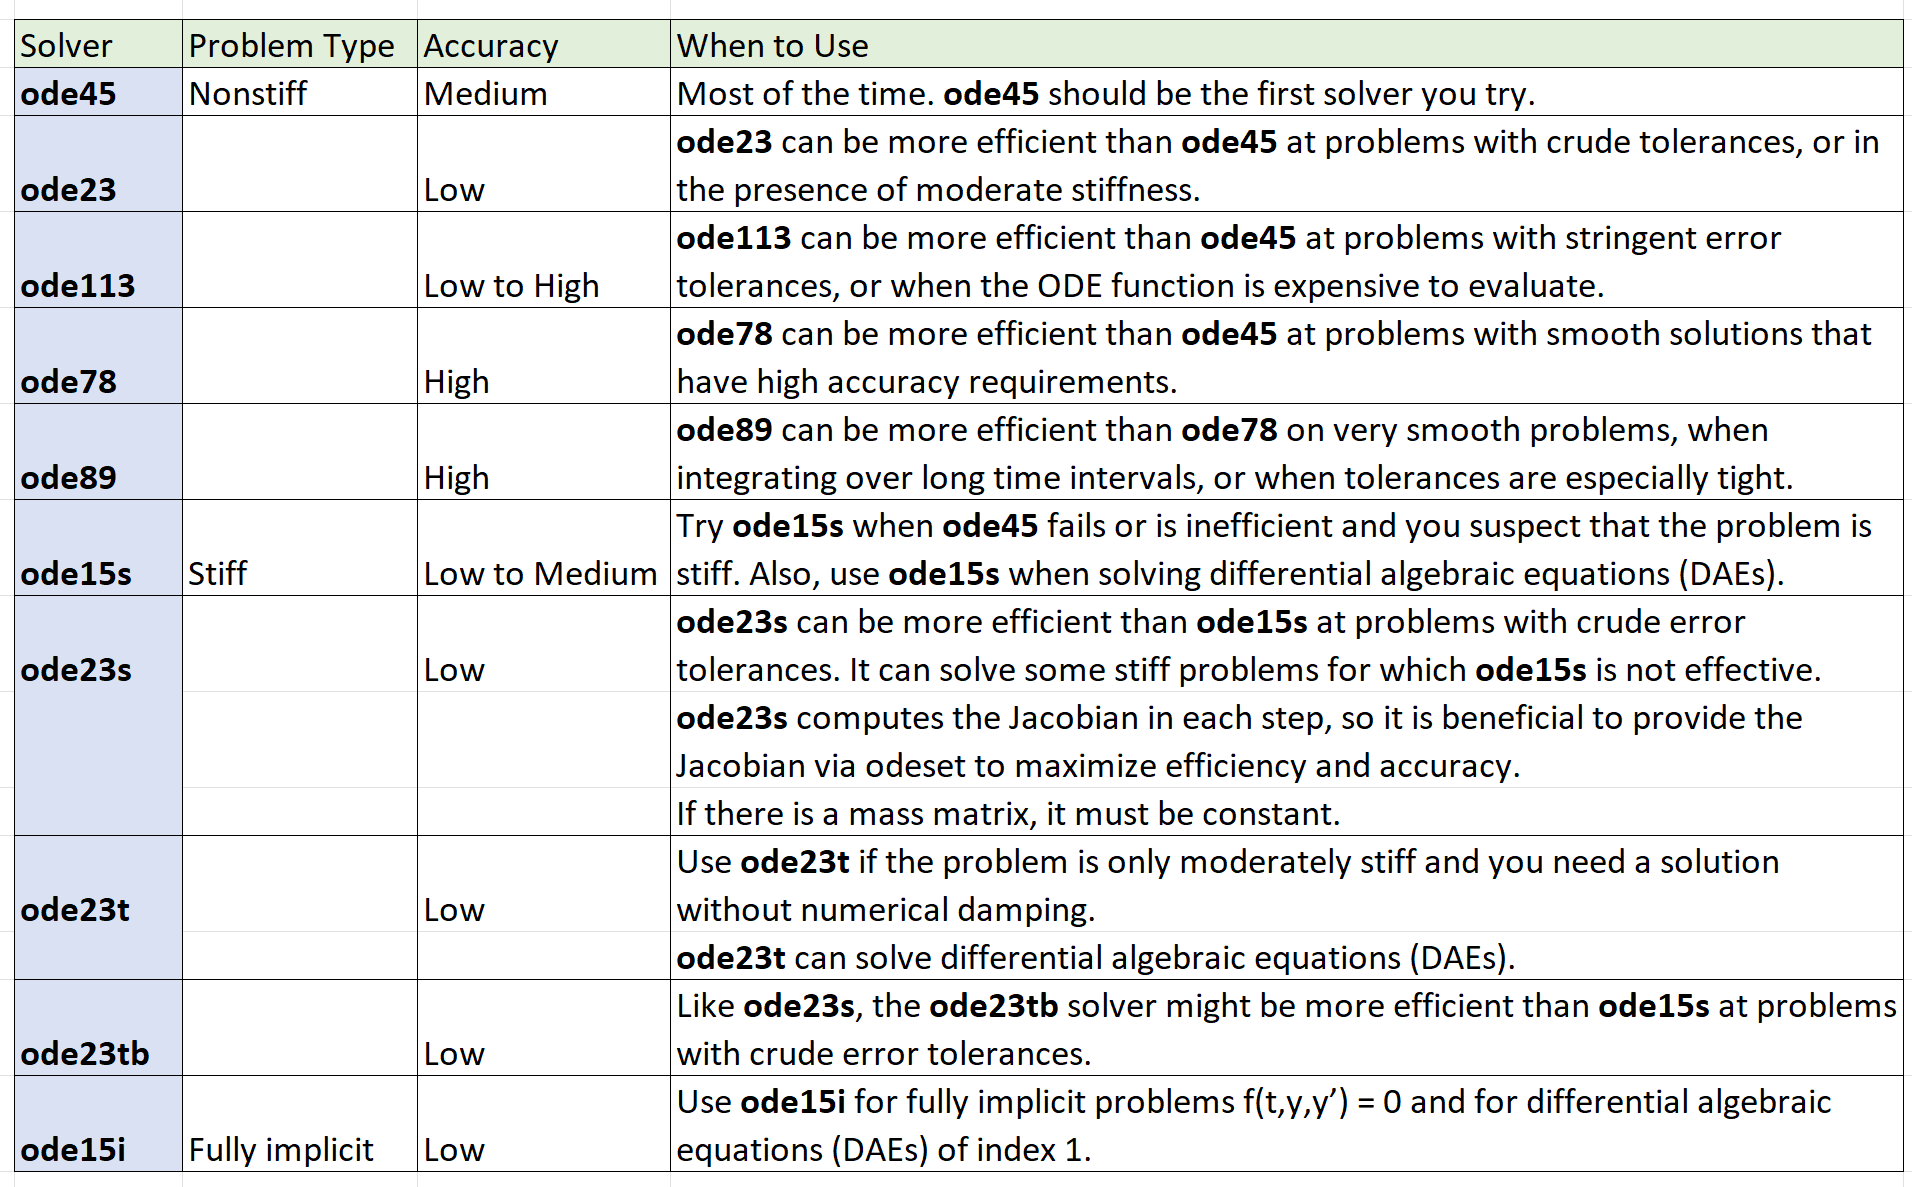

TIP: [Choosing a solver](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)